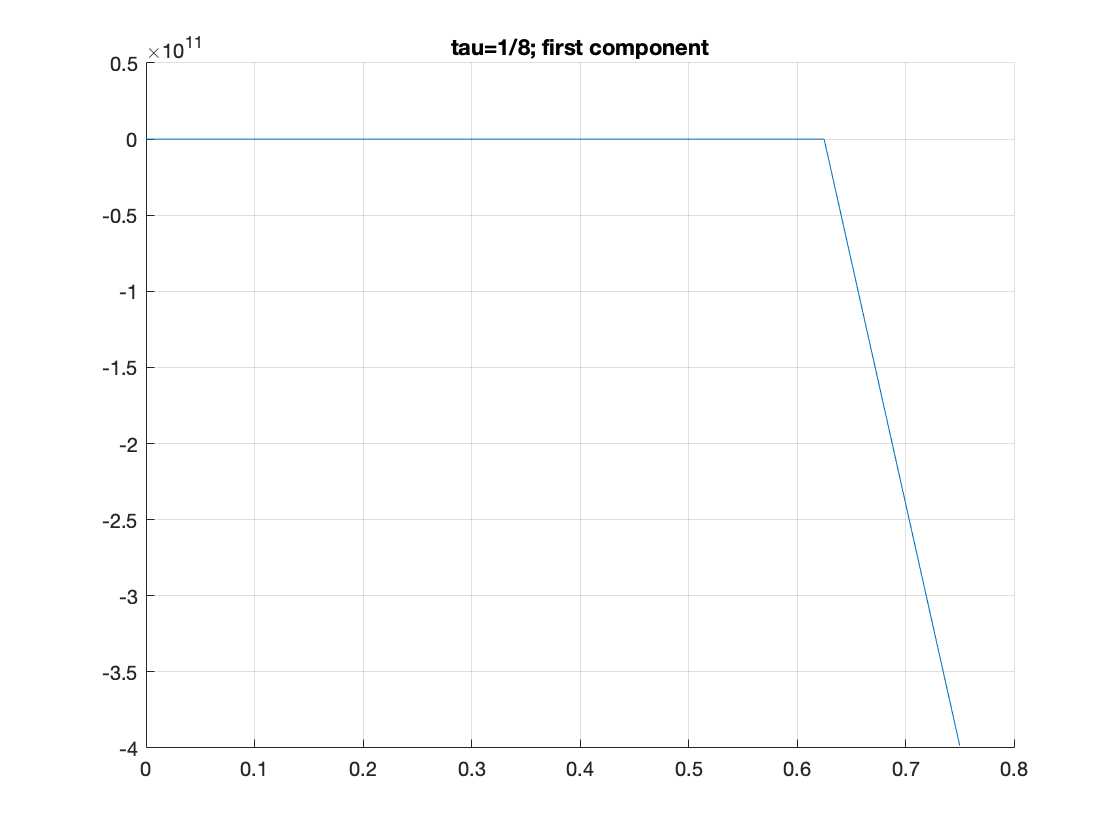


%-------------------------------------TASK-1-------------------------------------
%Параметры схемы и задачи
A = [ 0 0; 1/2 0];
a = [0; 1/2];
b = [0 1];

tau1 = 1/8;
tau2 = 1/128;

mesh1 = [0:tau1:0.75];
mesh2 = [0:tau2:0.75];

mesh1_value = zeros(2,length(mesh1));
mesh2_value = zeros(2,length(mesh2));

mesh1_value(:,1) = 1;
mesh2_value(:,1) = 1;

%Рассчет по схеме РК-2 (предиктор корректор)
for k = 1:1:length(mesh1)-1
    mesh1_value(:,k+1) = mesh1_value(:,k) + tau1*RHS(mesh1(k)+tau1*a(2),mesh1_value(:,k) + tau1/2*RHS(mesh1(k)+tau1*a(1), mesh1_value(:,k)));
end

for k = 1:1:length(mesh2)-1  
    mesh2_value(:,k+1) = mesh2_value(:,k) + tau2*RHS(mesh2(k)+tau2*a(2),mesh2_value(:,k) + tau2/2*RHS(mesh2(k)+tau2*a(1), mesh2_value(:,k)));
end

%Визуализация
hold on
grid on
plot(mesh1,mesh1_value(1,:))
title('tau=1/8; first component')

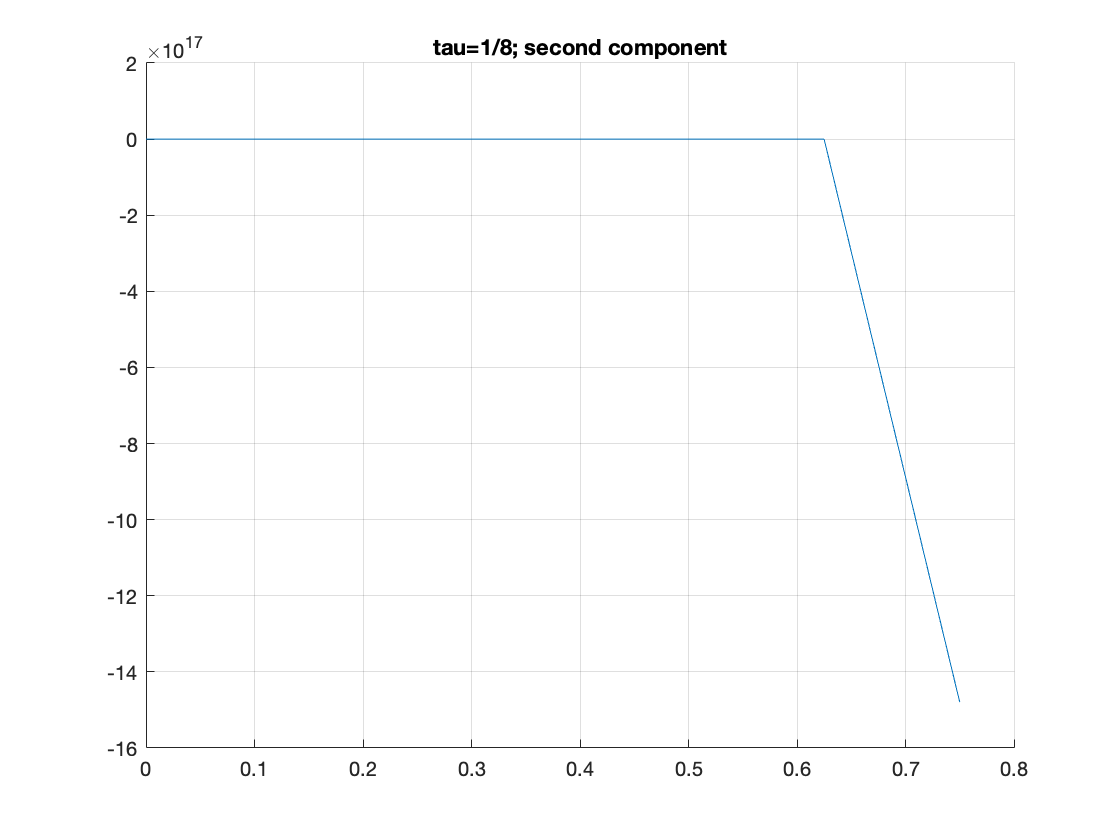


figure(2)
hold on
grid on
plot(mesh1,mesh1_value(2,:))
title('tau=1/8; second component')

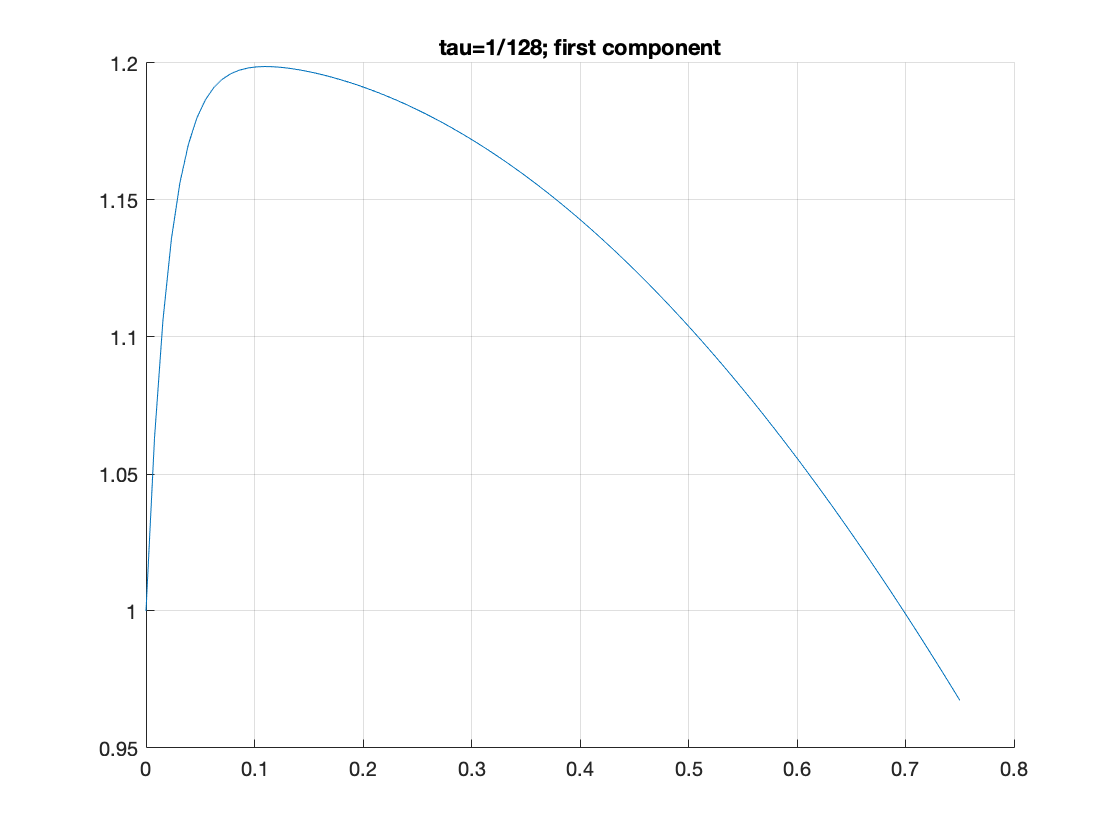


figure(3)
hold on
grid on
plot(mesh2,mesh2_value(1,:))
title('tau=1/128; first component')

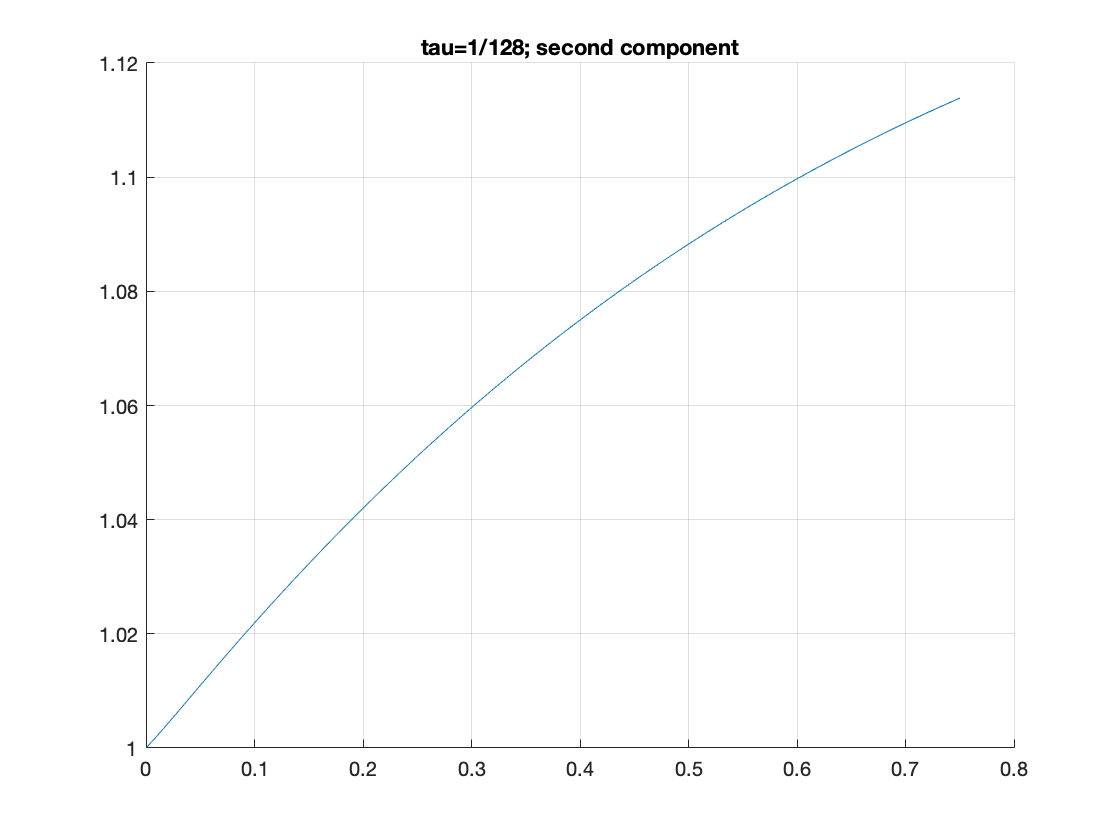


figure(4)
hold on
grid on
plot(mesh2,mesh2_value(2,:))
title('tau=1/128; second component')

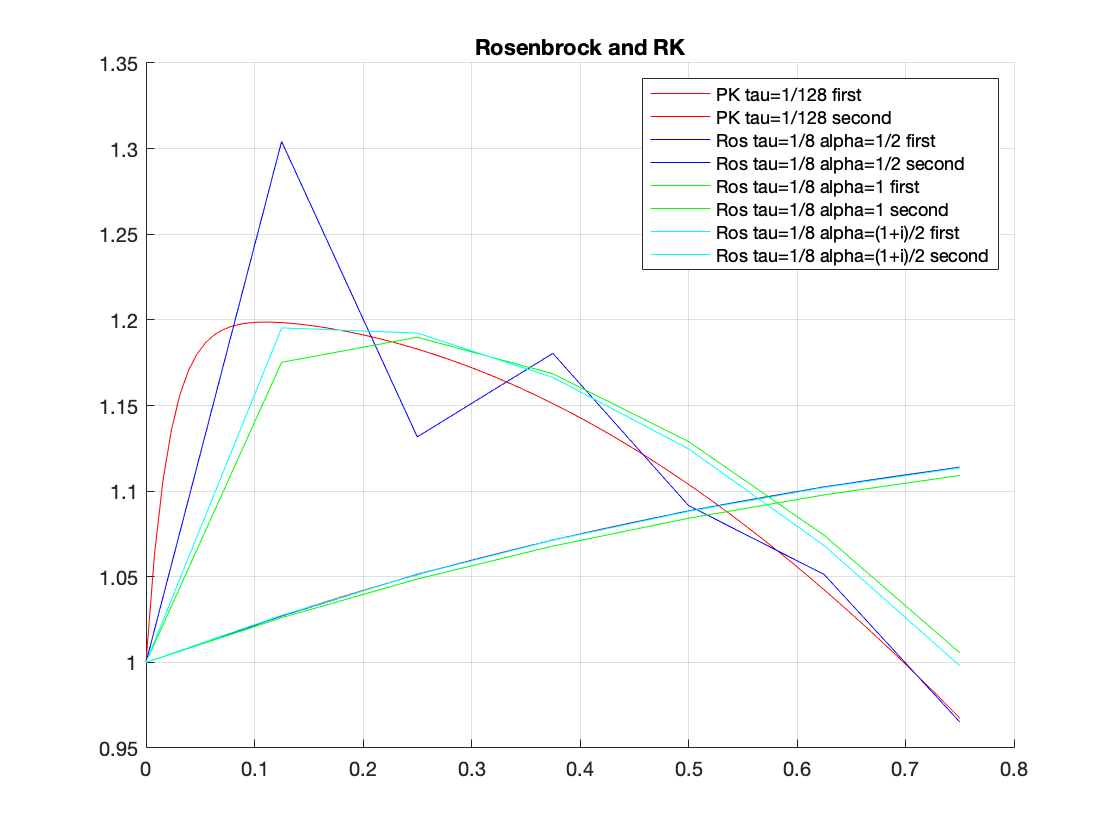


mesh2_value;


%-------------------------------------TASK-2-------------------------------------
figure(5)
hold on; grid on
[mesh,u] = ROS(0,0.75,1/8,1/2,[1,1]);
plot(mesh2,mesh2_value(1,:),'r')
plot(mesh2,mesh2_value(2,:),'r')
plot(mesh,u(1,:),'b')
plot(mesh,u(2,:),'b')

hold on; grid on
[mesh,u] = ROS(0,0.75,1/8,1,[1,1]);
plot(mesh,u(1,:),'g')
plot(mesh,u(2,:),'g')

hold on; grid on
[mesh,u] = ROS(0,0.75,1/8,(1+j)/2,[1,1]);
plot(mesh,u(1,:),'c')
plot(mesh,u(2,:),'c')


title('Rosenbrock and RK')
legend('РК tau=1/128 first', 'РК tau=1/128 second', 'Ros tau=1/8 alpha=1/2 first', 'Ros tau=1/8 alpha=1/2 second', 'Ros tau=1/8 alpha=1 first','Ros tau=1/8 alpha=1 second','Ros tau=1/8 alpha=(1+i)/2 first', 'Ros tau=1/8 alpha=(1+i)/2 second')